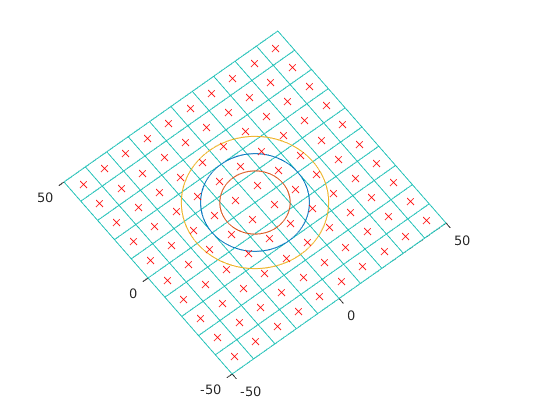

%% prepare grid & cell
d=2;

lc=10;
boxx=100;
xgc=-0.5*(boxx-lc):lc:0.5*(boxx-lc);
xgv=-boxx/2:lc:boxx/2;
[xv,yv]=meshgrid(xgv,xgv);
mesh(xv,yv,ones(size(xv)));


% cell
radc=20;
tt=linspace(0,2*pi,200);
xc=radc.*cos(tt);
yc=radc.*sin(tt);

ri=radc-sqrt(d)/2.*lc;
ro=radc+sqrt(d)/2.*lc;



hold on
plot3(xc,yc,ones(size(xc)))
plot3(ri.*cos(tt),ri.*sin(tt),ones(size(tt)))
plot3(ro.*cos(tt),ro.*sin(tt),ones(size(tt)))

[xxg,yyg]=meshgrid(xgc,xgc);
plot3(xxg,yyg,ones(size(xxg)),'xr')

## aplly function

d=2;

grad=sqrt(xxg.^2 + yyg.^2);

fl=sqrt(d)/2.*lc;

rg=(grad-radc)./fl;

ff=0.5.*rg.^3./abs(rg)-0.5.*rg+ 0.5;
ff(rg<=-1)=1;
ff(rg>=1)=0;
rg

rg =     6.1716    5.2338    4.4517    3.8798    3.5747    3.5747    3.8798    4.4517    5.2338    6.1716
    5.2338    4.1716    3.2543    2.5567    2.1716    2.1716    2.5567    3.2543    4.1716    5.2338
    4.4517    3.2543    2.1716    1.2947    0.7771    0.7771    1.2947    2.1716    3.2543    4.4517
    3.8798    2.5567    1.2947    0.1716   -0.5924   -0.5924    0.1716    1.2947    2.5567    3.8798
    3.5747    2.1716    0.7771   -0.5924   -1.8284   -1.8284   -0.5924    0.7771    2.1716    3.5747
    3.5747    2.1716    0.7771   -0.5924   -1.8284   -1.8284   -0.5924    0.7771    2.1716    3.5747
    3.8798    2.5567    1.2947    0.1716   -0.5924   -0.5924    0.1716    1.2947    2.5567    3.8798
    4.4517    3.2543    2.1716    1.2947    0.7771    0.7771    1.2947    2.1716    3.2543    4.4517
    5.2338    4.1716    3.2543    2.5567    2.1716    2.1716    2.5567    3.2543    4.1716    5.2338
    6.1716    5.2338    4.4517    3.8798    3.5747    3.5747    3.8798    4.4517    5.

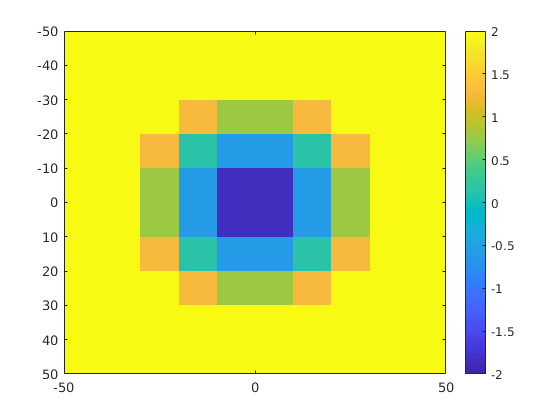



figure

%mesh(xxg,yyg,ff)
imagesc(xgc,xgc,rg)
caxis([-2 2])
colorbar